### Removing Power Line Interference of 60Hz Using FIR Notch Filter 

clc;
clear all;
close all;

%Loaded ECG Signal
load('100m.mat')

%Removing Gain and Base
ECGsignal_original = (val -1024)/100;
Fs = 200;
f1 = 60;   

t = (0:length(ECGsignal_original)-1)/Fs;

%Generating Noise for f1 = 60 Hz
N= 0.1*cos (2*pi*f1*t);

%Adding Noise to ECG signal
ECG_Noise = ECGsignal_original + N;


%FIR Notch Filter Designing
b = [1 0.618 1];
a = 1;

%Making the Gain = 1
b = b/sum(b);

%Transfer Function of the filter
t1 = tf(b,a,(1/Fs))

t1 =
 
  0.382 z^2 + 0.2361 z + 0.382
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


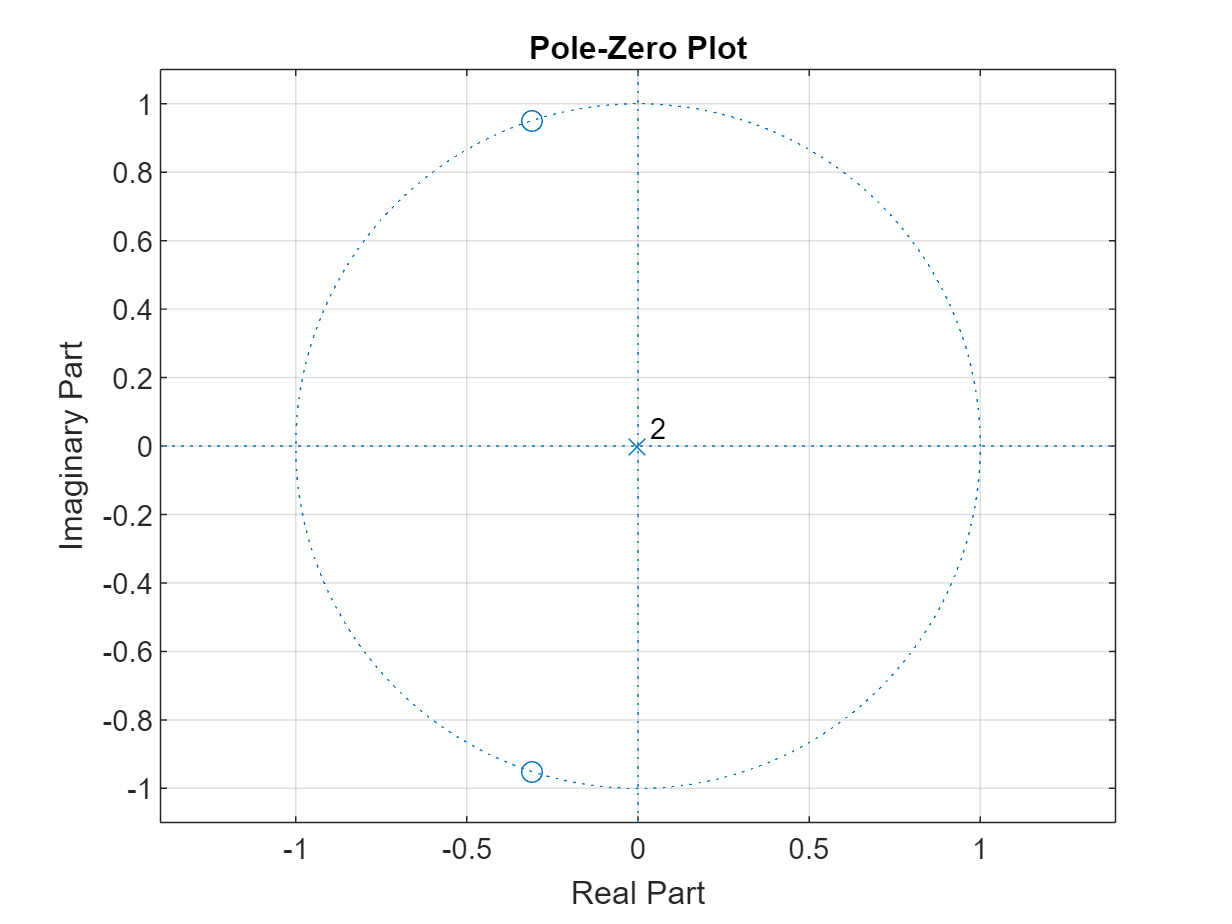

[z,p,k] = tf2zpk(b,a);

%pole zero plot
zplane(z,p)
grid on

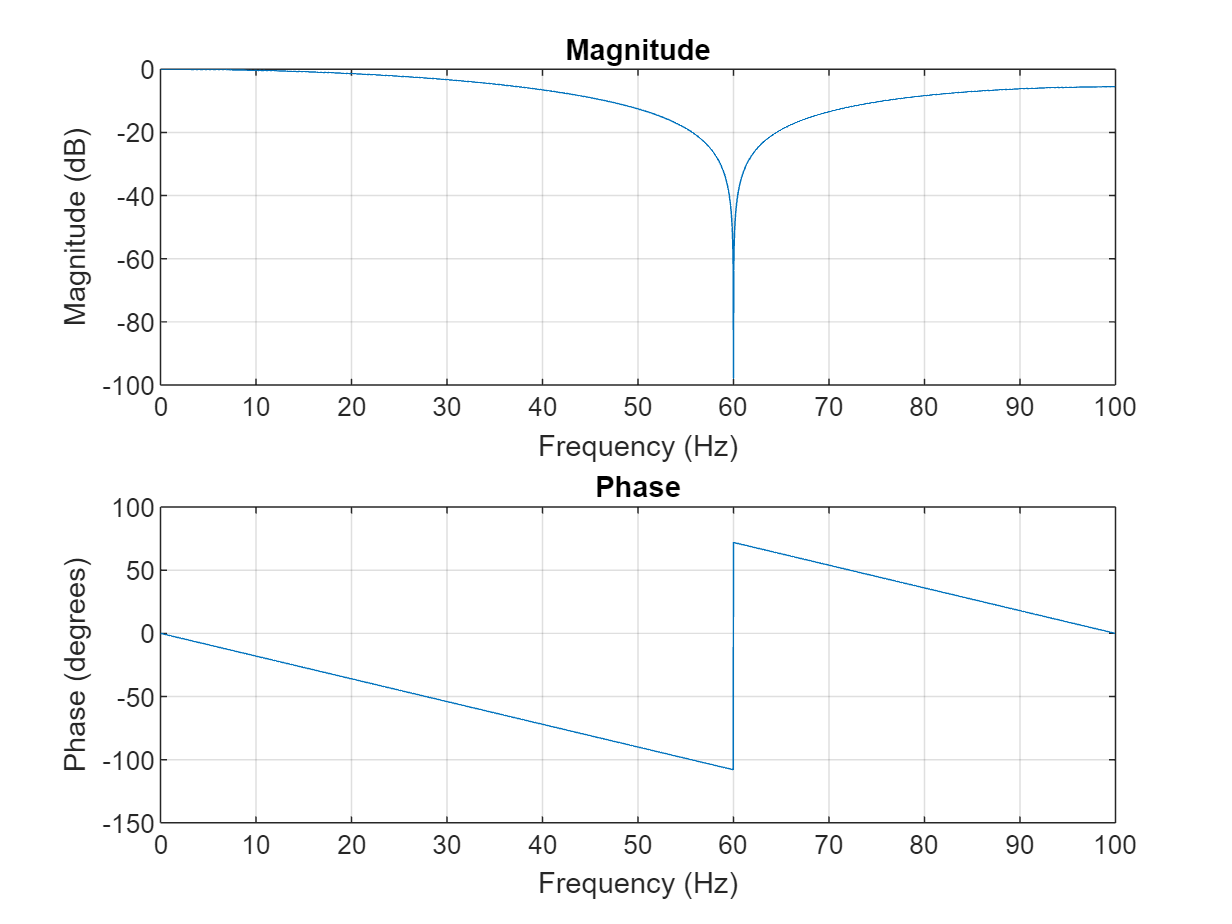

%Plotting the frequency response and group delay for the filter
L = length(ECGsignal_original);
freqz(b,a,L,Fs);

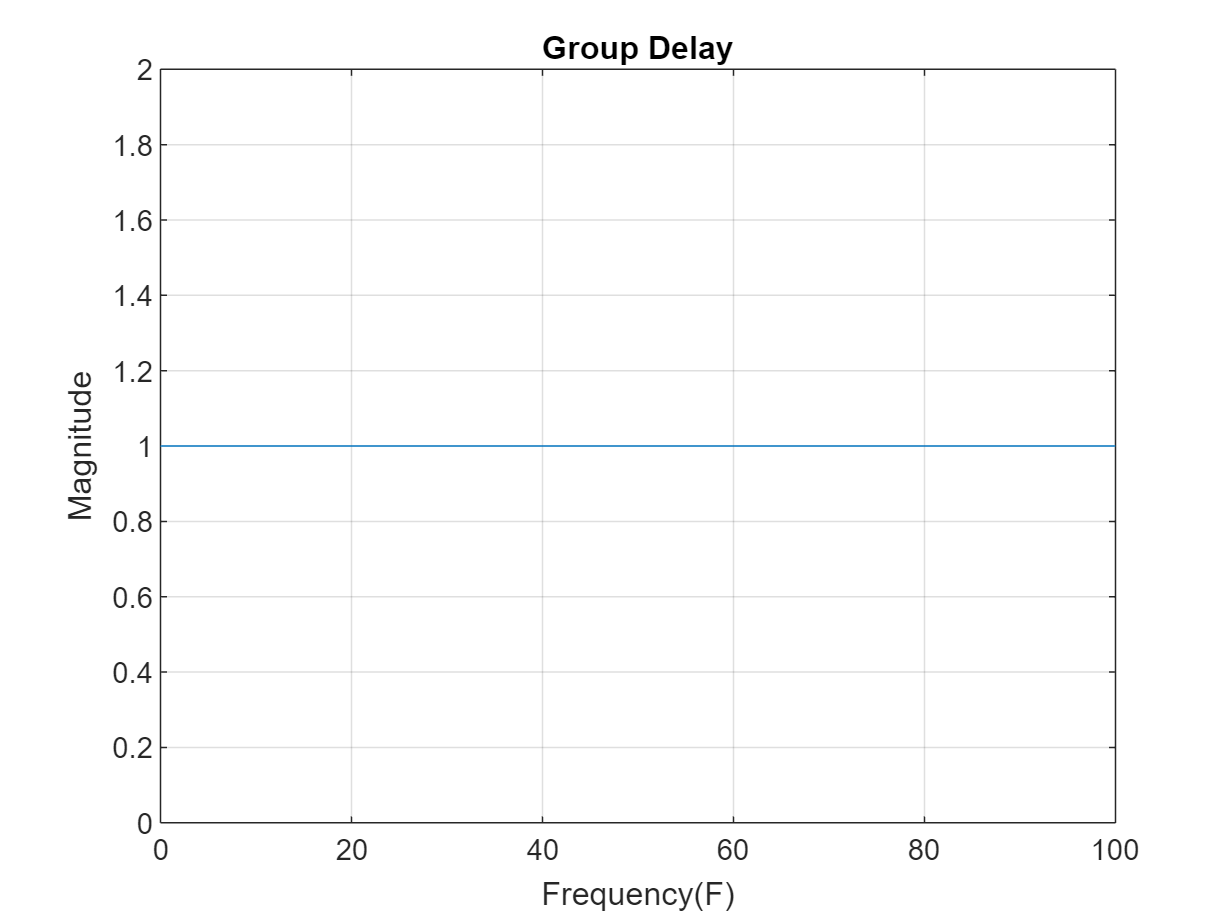

[Gd,f] = grpdelay(b,a,L,Fs);
plot(f,abs(Gd))
title('Group Delay')
xlabel('Frequency(F)')
ylabel('Magnitude')
grid on

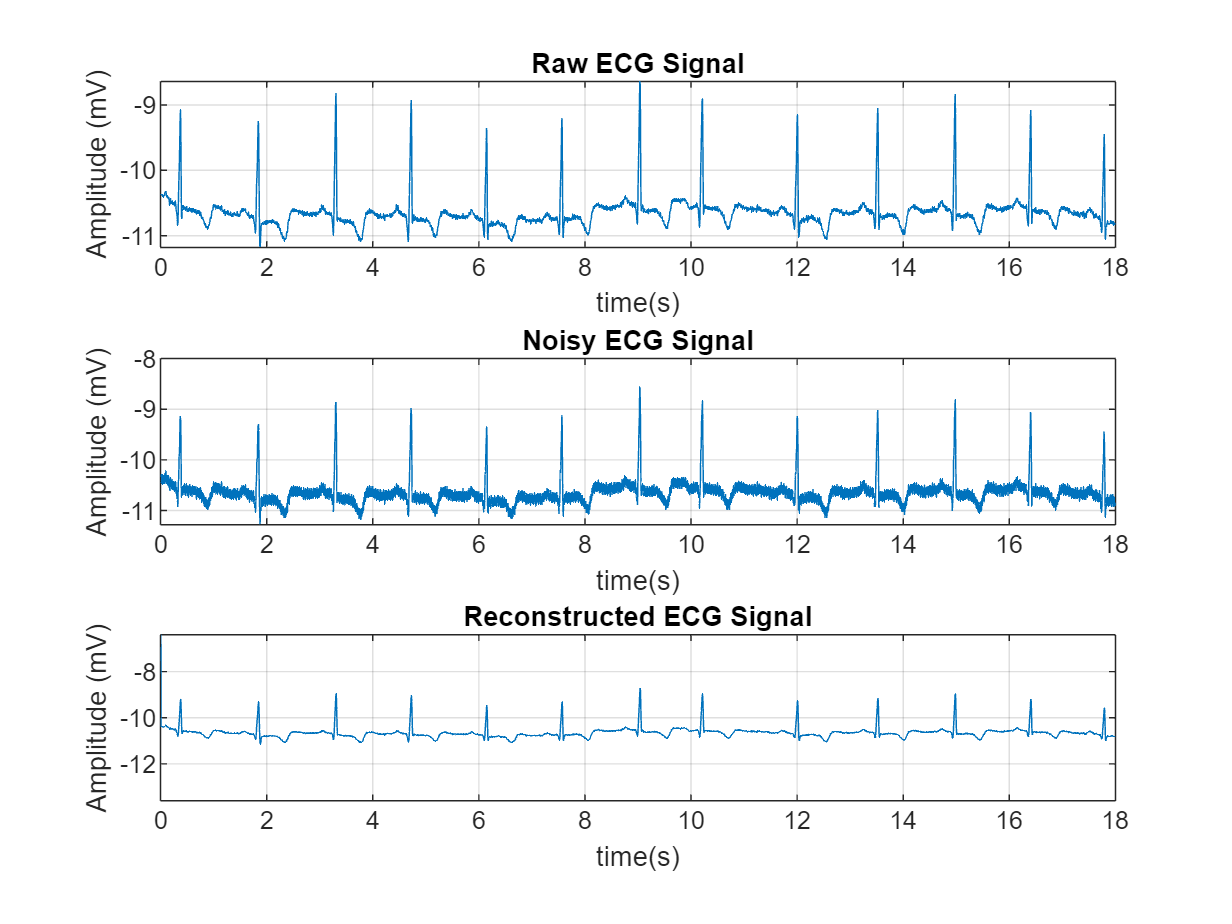

%Plotting the signals 
figure(2)
ECG_Filtered = filter(b,a,ECG_Noise);
subplot(311);
plot(t,ECGsignal_original)
xlabel('time(s)')
ylabel('Amplitude (mV)')
title('Raw ECG Signal')
grid on
subplot(312)
plot(t,ECG_Noise)
xlabel('time(s)')
ylabel('Amplitude (mV)')
title('Noisy ECG Signal')
grid on
subplot(313)
plot(t,ECG_Filtered)
xlabel('time(s)')
ylabel('Amplitude (mV)')
title('Reconstructed ECG Signal')
subplot(3,1,3)
xlim([0.0 18.0])
ylim([-13.6 -6.4])
grid on

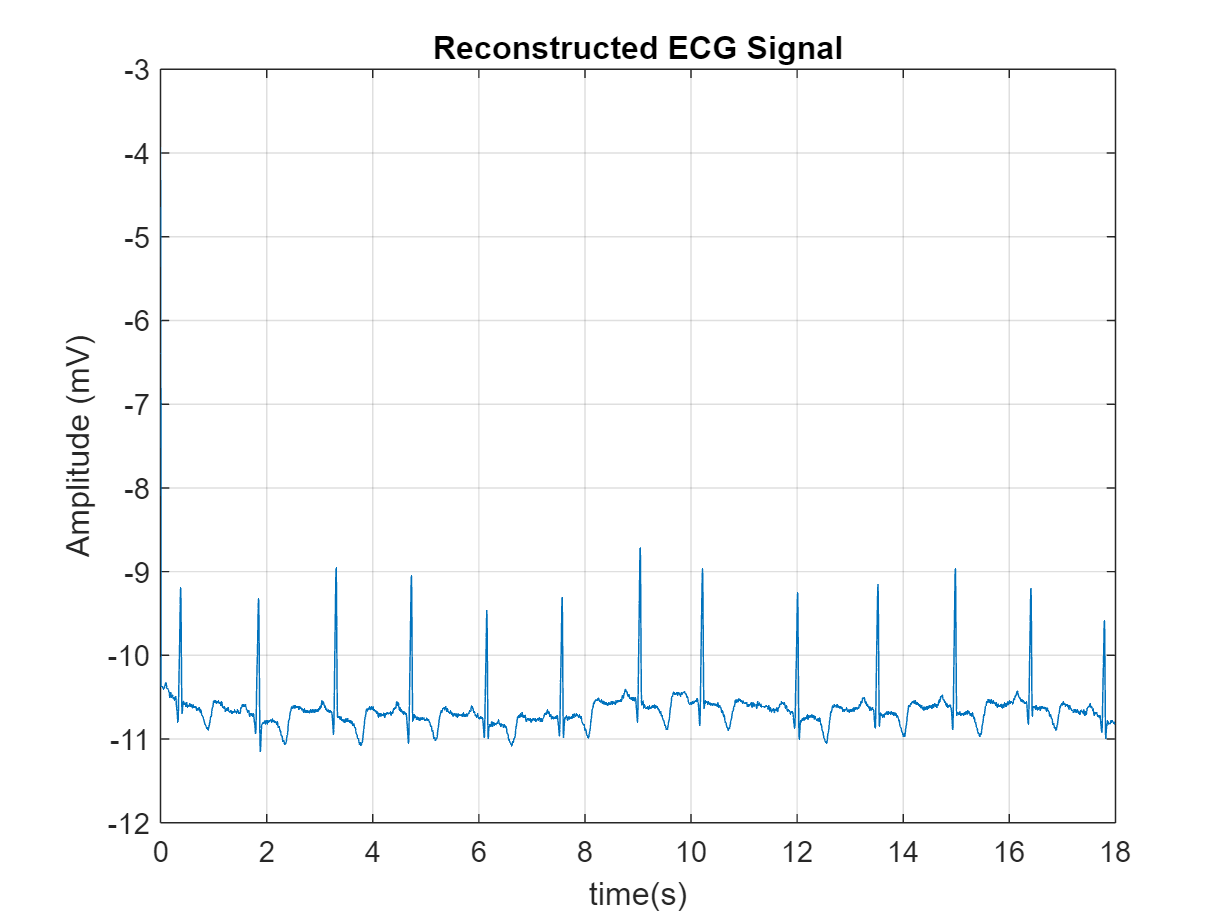

figure(3)
plot(t,ECG_Filtered)
xlabel('time(s)')
ylabel('Amplitude (mV)')
title('Reconstructed ECG Signal')
grid on